# LPF $\Gamma$ input to a uniform Transmission line

`The line is as follows`

- `L = 200 `$\mu$

- 
$$Z_L = 70 + j\omega 3\times10^9 \Omega$$


- 
$$R_g=50 \Omega$$


- `W = S = 20 `$\mu$

L = 200e-6;
W = 20e-6;
S = W;

Make a Coupled Microstrip Transmisison Line

coupledmicrostrip = coupledMicrostripLine(Length=200e-6, ...
                                            Width=20e-6, ...
                                            Spacing=20e-6, ...
                                            Height = 10e-6, ...
                                            GroundPlaneWidth=200e-6 ...
                                         )

coupledmicrostrip =   coupledMicrostripLine with properties:

              Length: 2.0000e-04
               Width: 2.0000e-05
             Spacing: 2.0000e-05
              Height: 1.0000e-05
    GroundPlaneWidth: 2.0000e-04
           Substrate: [1×1 dielectric]
           Conductor: [1×1 metal]


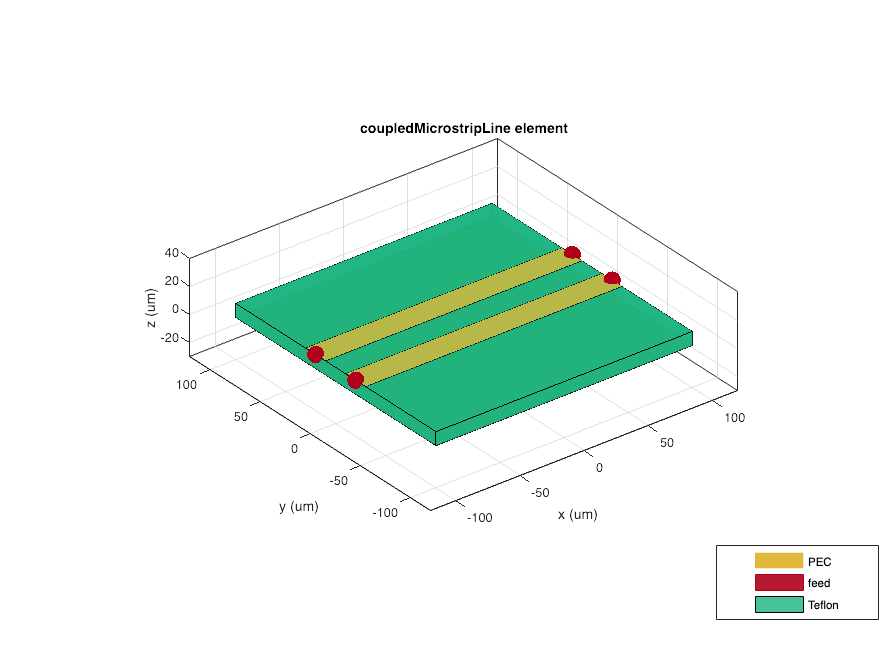

show(coupledmicrostrip)

Charactaristic Impedance

l = 2.5;

choice_arr = zeros(1, N);
epsz = zeros(1, N);

curr_Gamma0 = Gamma0;
num_pts = 1e2;
z = linspace(0, l, num_pts); % z across the length of the element

Gamma_element_on = zeros(num_pts, length(Gamma0));
Gamma_element_off = zeros(num_pts, length(Gamma0));

[Beta_on, Beta_off, alpha_on, alpha_off] = find_Beta(w, epsilon0, mu0);
Gamma_element_on = synthesize_Gamma_of_element(curr_Gamma0, alpha_on, Beta_on, l, num_pts, Gamma_element_on);
Gamma_element_off = synthesize_Gamma_of_element(curr_Gamma0, alpha_off, Beta_off, l, num_pts, Gamma_element_off);
[choice, d_on, d_off, next_Gamma0] = choose_switch_for_element(Gamma_element_on, Gamma_element_off, curr_Gamma0); % choose which ever is closer to the og
%Gamma_element_on == Gamma_element_off;
%figure;
%plot_switch_comparison(w, Gamma0, Gamma_element_on(50, :), Gamma_element_off(50, :));
curr_Gamma0 = next_Gamma0;
choice_arr(1) = choice;

figure
plot_resp_logy(w, Gamma0, "Gamma0")

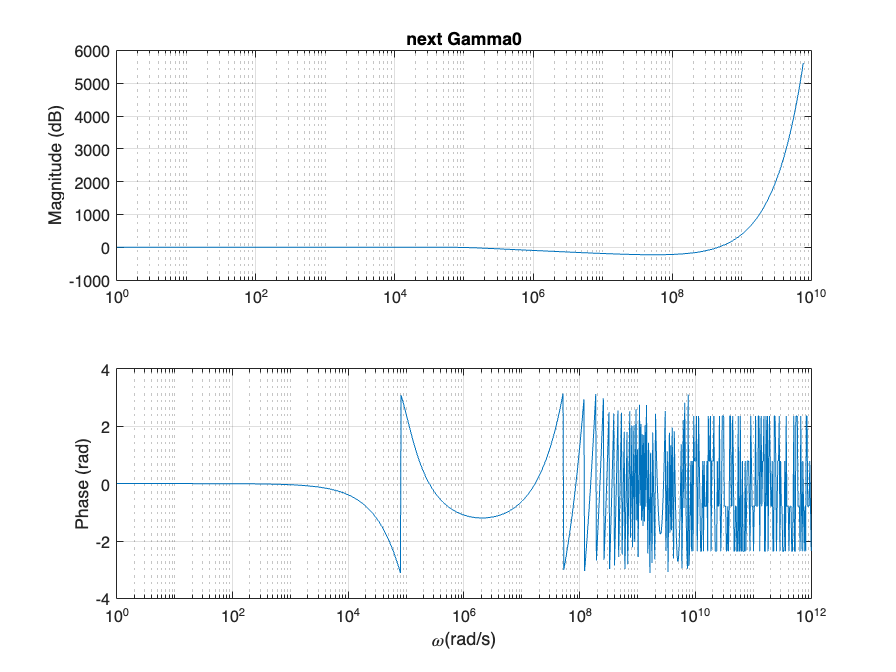

figure
plot_resp_logy(w, next_Gamma0, "next Gamma0")

%{
figure
plot3(w, z, Gamma_element_on)

figure
plot3(w, z, Gamma_element_off)
%}

function plot_resp_logy(x, y, name) % plot functions with dB in y
    subplot(2, 1, 1)
    semilogx(x, 20*log(abs(y))/log(10))
    title(name)
    ylabel("Magnitude (dB)")
    grid("on")
    subplot(2, 1, 2)
    semilogx(x, angle(y))
    ylabel("Phase (rad)")
    xlabel("\omega(rad/s)")
    grid("on")
end

function plot_resp(x, y, name) % plot functions
    subplot(2, 1, 1)
    semilogx(x, abs(y))
    title(name)
    ylabel("Magnitude (dB)")
    grid("on")
    subplot(2, 1, 2)
    semilogx(x, angle(y))
    ylabel("Phase (rad)")
    xlabel("\omega(rad/s)")
    grid("on")
end

function plot_switch_comparison(w, Gamma0, Gamma_on, Gamma_off)
    subplot(3, 1, 1)
    semilogx(w, 20*log(abs(Gamma0))/log(10))
    ylabel("\Gamma(\omega, z=0)")
    grid("on")
    subplot(3, 1, 2)
    semilogx(w, 20*log(abs(Gamma_on))/log(10))
    ylabel("\Gamma_{on}(\omega)")
    grid("on")
    subplot(3, 1, 3)
    semilogx(w, 20*log(abs(Gamma_off))/log(10))
    ylabel("\Gamma_{off}(\omega)")
    grid("on")
    xlabel("\omega(rad/s)")
end

function [Beta_on, Beta_off, alpha_on, alpha_off] = find_Beta(w, epsilon0, mu0) % finds the value of Beta_on
    % Beta = w*sqrt(L*C) where L and C are per unit length
    Beta_on = w.*sqrt(30*epsilon0*mu0);
    Beta_off = w.*sqrt(epsilon0*mu0);
    alpha_on = Beta_on;
    alpha_off = Beta_off;
end

function Gamma_element = synthesize_Gamma_of_element(Gamma0, alpha, Beta, l, num_pts, Gamma_element) % find Gamma across a element when switch in on
    z = linspace(0, l, num_pts); % z across the length of the element
    for i = 1:num_pts
        Gamma_element(i, :) = Gamma0.*exp(2.*(alpha + 1j.*Beta).*z(i));
    end
end

function [choice, d_on, d_off, next_Gamma0] = choose_switch_for_element(Gamma_element_on, Gamma_element_off, Gamma0) % chooses the optimal value of Gamma and returns the Gamm0 for next element
    d_on = 0; d_off = 0;
    for i = 1:length(Gamma_element_on(:, 1))
        d_on = d_on + compute_dist_between_arr(Gamma_element_on(i, : ), Gamma0);
        d_off = d_off + compute_dist_between_arr(Gamma_element_off(i, : ), Gamma0);
    end
    if (d_on <= d_off)
        choice = 1;
    else
        choice = -1;
    end
   %next_Gamma0 = zeros(1, length(Gamma0));
    next_Gamma0 = Gamma_element_on(length(Gamma_element_on(:, 1)), :);
end

function d = compute_dist_between_arr(x, y)
    darr = abs(x-y);
    d = sum(darr);
end

